fname = 'rabbit.bag';
% Create a bag file object with the file name by omitting the
% semicolon this displays some information about the bag file
bag = rosbag(fname);
  
% Display a list of the topics and message types in the bag file
bag.AvailableTopics

ans = 1×3 table
               NumMessages           MessageType                                                       MessageDefinition                                            
               ___________    __________________________    ________________________________________________________________________________________________________

    /rabbit        550        geometry_msgs/PointStamped    {'  uint32 Seq↵  Time Stamp↵  char FrameId↵geometry_msgs/Point Point↵  double X↵  double Y↵  double Z↵'}


 
%% Create a time series of the Odometry data
% Retrieve the messages as a cell array
geom_msgs = select(bag,'Topic','/rabbit');
 
% Create a timeseries object of the subset of message fields we are interested in
geom_ts = timeseries(geom_msgs,'Point.X','Point.Y');

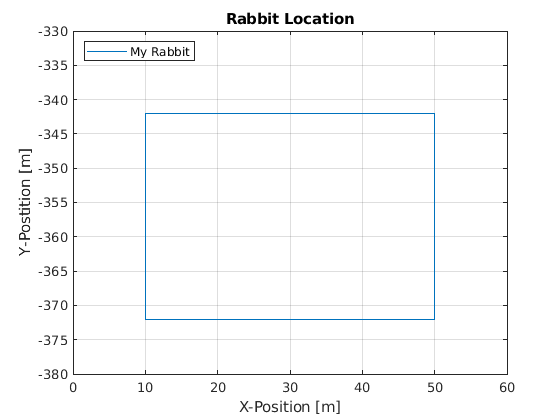

%% Plot X/Y Positions
figure(1); clf();
% Plot the Data index
plot(geom_ts.Data(:,1),geom_ts.Data(:,2))
xlabel('X-Position [m]')
ylabel('Y-Postition [m]')
legend('My Rabbit','Location','northwest')
grid on
title('Rabbit Location')
xlim([0 60])
ylim([-380 -330])

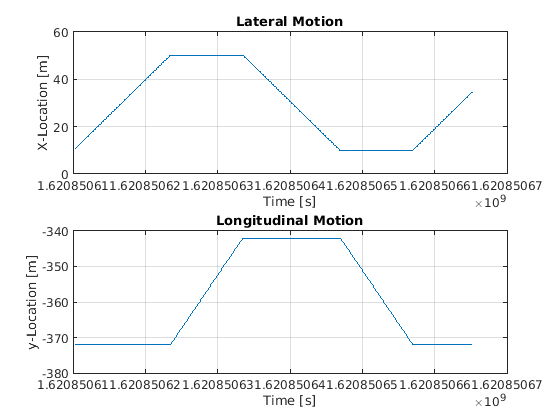

% plot x/y vs time 
figure (2); clf()
subplot(2,1,1)
plot(geom_ts.Time(:),geom_ts.Data(:,1))
grid on
title('Lateral Motion')
xlabel('Time [s]')
ylabel('X-Location [m]')
ylim([0 60])

subplot(2,1,2)
plot(geom_ts.Time(:),geom_ts.Data(:,2))
grid on
title('Longitudinal Motion')
xlabel('Time [s]')
ylabel('y-Location [m]')
ylim([-380 -340])